# I need to ivnestigate and understand standrads

clear all
clc
close all

From CVRL

2 deg CMF

CIE_1931_2_CMF     = csvread('ciexyz31.csv');
CIE_1931_2_CMF_J   = csvread('ciexyzj.csv');
CIE_1931_2_CMF_JV  = csvread('ciexyzjv.csv');
CIE_1964_10_CMF    = csvread('ciexyz64.csv');

10 deg CMF

Note that these are both (even the 10 deg) transformed from 2 degree LMS cone fundamentals

CIE_2006_2_CMF      = csvread('lin2012xyz2e_1_7sf.csv');
CIE_2006_10_CMF     = csvread('lin2012xyz10e_1_7sf.csv'); %Note that this is 


Plot The CMFs for 2 deg and then 10 deg

close all
CMF_Standards_Fig = figure(1)

CMF_Standards_Fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties



sp_1 = subplot(2,1,1)

sp_1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


hold on
title('2 degree CMFs')

CMF2deg_p      = plot( CIE_1931_2_CMF(:,1)     , CIE_1931_2_CMF(:,2:end)    ,'r'); %Color Order Like Rainbow chronologically ROYGBIV
CMF2deg_J_p    = plot( CIE_1931_2_CMF_J(:,1)   , CIE_1931_2_CMF_J(:,2:end)  ,'g'); %plot 3 curves
CMF2deg_JV_p   = plot( CIE_1931_2_CMF_JV(:,1)  , CIE_1931_2_CMF_JV(:,2:end) ,'b');
CMF2deg_LMS_p  = plot( CIE_2006_2_CMF(:,1)     , CIE_2006_2_CMF(:,2:end)    ,'m');

set(sp_1, 'XLim',[360,700])
lgd1 = legend(sp_1, [CMF2deg_p(1,:),  CMF2deg_J_p(1,:),     CMF2deg_JV_p(1,:),          CMF2deg_LMS_p(1,:)],...
                    '1931 2deg CMFs','1931 2deg Judd CMFs', '1931 CMF Judd & Vos CMFs', '2deg CMFs From 2006 LMS')

lgd1 =   Legend (1931 2deg CMFs, 1931 2deg Judd CMFs, 1931 CMF Judd & Vos CMFs, 2deg CMFs From 2006 LMS) with properties:

         String: {'1931 2deg CMFs'  '1931 2deg Judd CMFs'  '1931 CMF Judd & Vos CMFs'  '2deg CMFs From 2006 LMS'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.5435 0.7623 0.3429 0.1464]
          Units: 'normalized'

  Show all properties




sp_2 = subplot(2,1,2)

sp_2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


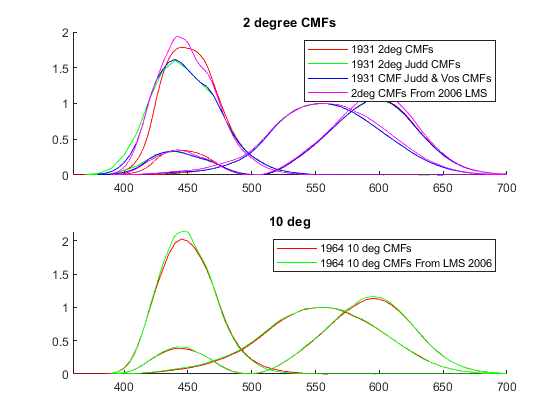

lgd2 =   Legend (1964 10 deg CMFs, 1964 10 deg CMFs From LMS 2006) with properties:

         String: {'1964 10 deg CMFs'  '1964 10 deg CMFs From LMS 2006'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.4881 0.3551 0.3982 0.0774]
          Units: 'normalized'

  Show all properties


hold on
title('10 deg CMFs')
CMF10deg_1964_p = plot(CIE_1964_10_CMF(:,1), CIE_1964_10_CMF(:,2:end),'r');
CMF10deg_2006_p = plot(CIE_2006_10_CMF(:,1), CIE_2006_10_CMF(:,2:end),'g');

set(sp_2, 'XLim',[360,700])
lgd2 = legend( sp_2, [CMF10deg_1964_p(1,:), CMF10deg_2006_p(1,:)],...
                     {'1964 10 deg CMFs',      '1964 10 deg CMFs From LMS 2006'} )